syms x 
v = linspace(-6, 6, 120)

v =    -6.0000   -5.8992   -5.7983   -5.6975   -5.5966   -5.4958   -5.3950   -5.2941   -5.1933   -5.0924   -4.9916   -4.8908   -4.7899   -4.6891   -4.5882   -4.4874   -4.3866   -4.2857   -4.1849   -4.0840   -3.9832   -3.8824   -3.7815   -3.6807   -3.5798   -3.4790   -3.3782   -3.2773   -3.1765   -3.0756   -2.9748   -2.8739   -2.7731   -2.6723   -2.5714   -2.4706   -2.3697   -2.2689   -2.1681   -2.0672   -1.9664   -1.8655   -1.7647   -1.6639   -1.5630   -1.4622   -1.3613   -1.2605   -1.1597   -1.0588


w = v(v~=0)

w =    -6.0000   -5.8992   -5.7983   -5.6975   -5.5966   -5.4958   -5.3950   -5.2941   -5.1933   -5.0924   -4.9916   -4.8908   -4.7899   -4.6891   -4.5882   -4.4874   -4.3866   -4.2857   -4.1849   -4.0840   -3.9832   -3.8824   -3.7815   -3.6807   -3.5798   -3.4790   -3.3782   -3.2773   -3.1765   -3.0756   -2.9748   -2.8739   -2.7731   -2.6723   -2.5714   -2.4706   -2.3697   -2.2689   -2.1681   -2.0672   -1.9664   -1.8655   -1.7647   -1.6639   -1.5630   -1.4622   -1.3613   -1.2605   -1.1597   -1.0588


n = length(w);      % Determine the length of the input vector
alpha_vec = zeros(n,1); % Initialize the output vector

for i=1:n
    alpha_vec(i) = myAlpha(w(i));   % Compute the value of myAlpha at each element of w
end
alpha_vec = alpha_vec.'; % Transpose the vector to make it a row vector
alpha_vec

alpha_vec =    -1.0506   -1.0522   -1.0539   -1.0557   -1.0575   -1.0595   -1.0615   -1.0636   -1.0659   -1.0683   -1.0707   -1.0734   -1.0762   -1.0791   -1.0822   -1.0855   -1.0890   -1.0927   -1.0967   -1.1008   -1.1053   -1.1101   -1.1151   -1.1206   -1.1264   -1.1327   -1.1394   -1.1466   -1.1544   -1.1628   -1.1720   -1.1819   -1.1926   -1.2044   -1.2172   -1.2313   -1.2469   -1.2640   -1.2830   -1.3041   -1.3276   -1.3541   -1.3840   -1.4180   -1.4568   -1.5014   -1.5533   -1.6142   -1.6865   -1.7734


plot(alpha_vec, w, 'o-');    % Plot alpha_vec vs. w as a line with markers
ylabel('Gamma Values') 
xlabel('Alpha Values')
aval = 0.1;
guess = 0.5;
inv_fun = @(x) (myAlpha(x) - aval);
S = fsolve(@(x) inv_fun(x), guess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


R(x) = 1- S*sqrt(x);
xint = double(solve(R(x) == 0));
yint = zeros(size(xint));
xint

xint = 0.2326

grid on
fplot(R(x), [0, 5])
title("Alpha = 0.1")
xlabel('t') 
ylabel('R(t)') 
hold on
plot(xint,yint, 'm*','MarkerSize', 10)
hold off
aval = 0.5;
inv_fun = @(x) (myAlpha(x) - aval);
S = fsolve(@(x) inv_fun(x), guess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


R(x) = 1- S*sqrt(x);
xint = double(solve(R(x) == 0));
yint = zeros(size(xint));
xint

xint = 0.8538

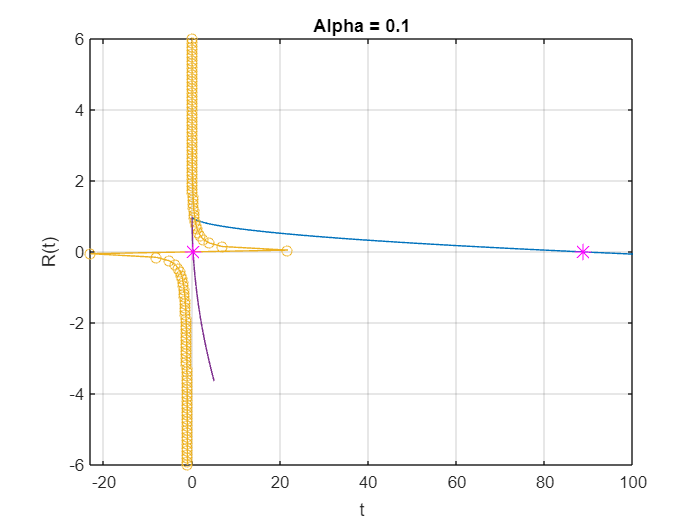

grid on

fplot(R(x), [0, 5])
title("Alpha = 0.5")
xlabel('t') 
ylabel('R(t)') 

grid on
hold on
plot(xint,yint, 'm*','MarkerSize', 10)
hold off
aval = 1;
inv_fun = @(x) (myAlpha(x) - aval);
S = fsolve(@(x) inv_fun(x), guess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


R(x) = 1- S*sqrt(x);
xint = double(solve(R(x) == 0));
yint = zeros(size(xint));
xint

xint = 1.9524

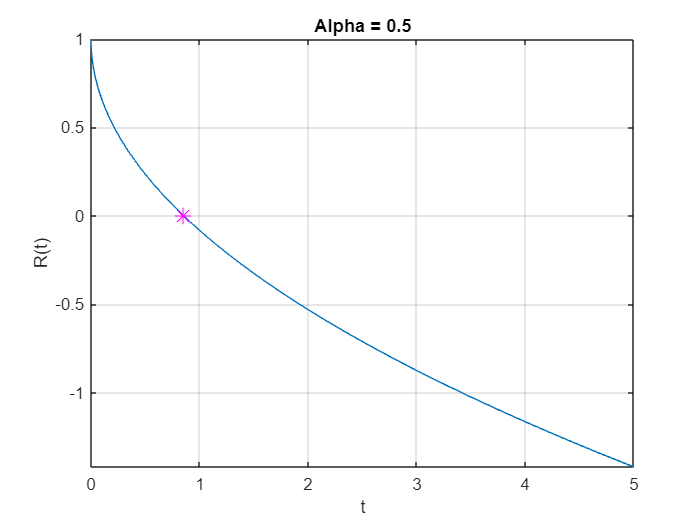

grid on


fplot(R(x), [0, 5])
title("Alpha = 1")
xlabel('t') 
ylabel('R(t)') 

grid on
hold on
plot(xint,yint, 'm*','MarkerSize', 10)

hold off
aval = 2;
inv_fun = @(x) (myAlpha(x) - aval);
S = fsolve(@(x) inv_fun(x), guess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


R(x) = 1- S*sqrt(x);
xint = double(solve(R(x) == 0));
yint = zeros(size(xint));
xint

xint = 5.3150

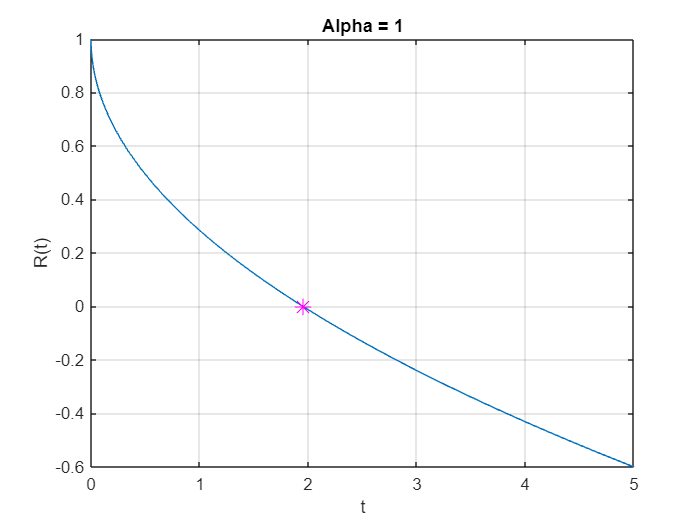

grid on

fplot(R(x), [0, 6])
title("Alpha = 2")
xlabel('t') 
ylabel('R(t)') 

grid on
hold on
plot(xint,yint, 'm*','MarkerSize', 10)

hold off
aval = 5;
inv_fun = @(x) (myAlpha(x) - aval);
S = fsolve(@(x) inv_fun(x), guess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


R(x) = 1- S*sqrt(x);
xint = double(solve(R(x) == 0));
yint = zeros(size(xint));
xint

xint = 24.8131

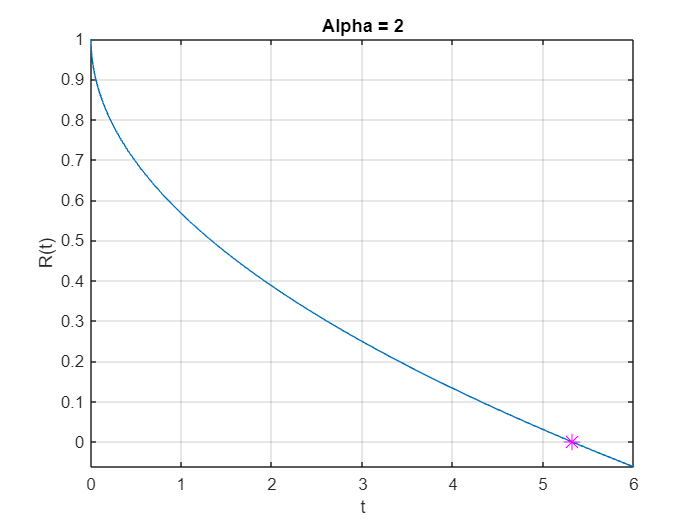

grid on

fplot(R(x), [0, 100])
title("Alpha = 5")
xlabel('t') 
ylabel('R(t)') 

grid on
hold on
plot(xint,yint, 'm*','MarkerSize', 10)

hold off
aval = 10;
inv_fun = @(x) (myAlpha(x) - aval);
S = fsolve(@(x) inv_fun(x), guess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


R(x) = 1- S*sqrt(x);
xint = double(solve(R(x) == 0));
xint

xint = 88.7197

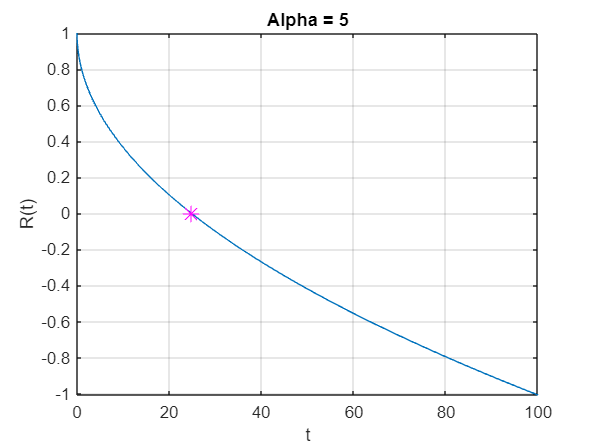

yint = zeros(size(xint));
grid on

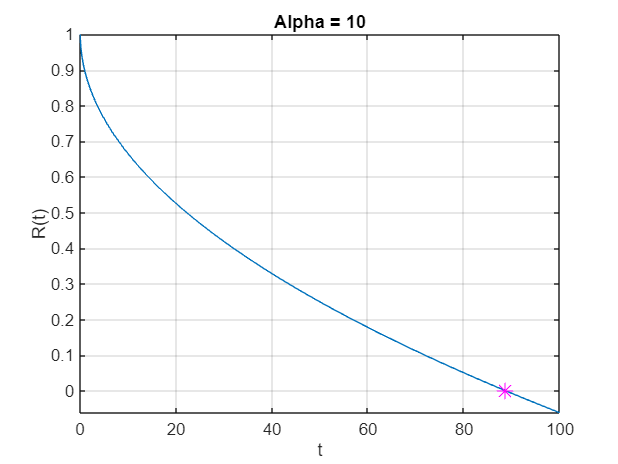

fplot(R(x), [0, 100])
title("Alpha = 10")
xlabel('t') 
ylabel('R(t)') 

grid on
hold on
plot(xint,yint, 'm*','MarkerSize', 10)

xint

xint = 88.7197

function a = myAlpha(x)
    a = double(2*exp(-x^2/4)/(sqrt(pi)*x* erfc(-x/2)));
end